Séance 3 -Signal   /    TP 1 - Communication Numérique

N =512 ; 
sigmab2 = 0.5;
g0 = 1;

An = genBPSK(N);
Bn = genBruitN(N, sigmab2);

VectN =    -0.0532   -0.4547   -0.5516    0.0867   -1.1799   -0.3571   -0.3896    0.1690    0.0908   -1.4509   -0.2962    0.2875   -0.2607    0.2115    1.2556    0.0240   -1.2344    0.7264   -0.9450   -0.2310   -0.0601   -1.5954    1.4555    0.4881   -0.0479    0.8556   -0.1082   -0.7844    0.5226    1.5587   -0.1174    0.6962   -0.2719    0.4527    0.1690   -1.0012   -1.6621    0.7114    1.1396    0.3877    1.1923    0.4849    0.8266   -0.4770    1.1643    0.4561   -0.6531    0.4224   -0.5530   -0.1096


Rn = An*g0 + Bn;
Anf = decodeBPSK(Rn);

VectAn =      1     1     1    -1    -1    -1    -1    -1     1    -1     1    -1    -1    -1     1    -1    -1    -1     1    -1    -1    -1     1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1    -1     1     1    -1     1    -1     1    -1     1     1    -1    -1    -1     1


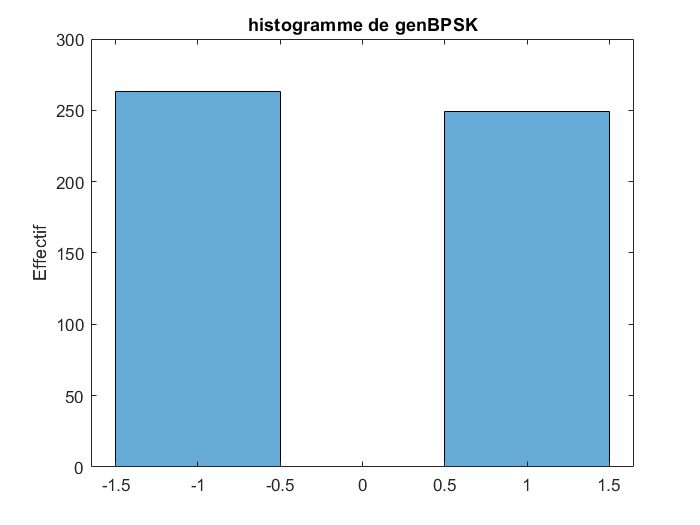

histogram(genBPSK(N))
ylabel("Effectif")
title("histogramme de genBPSK")

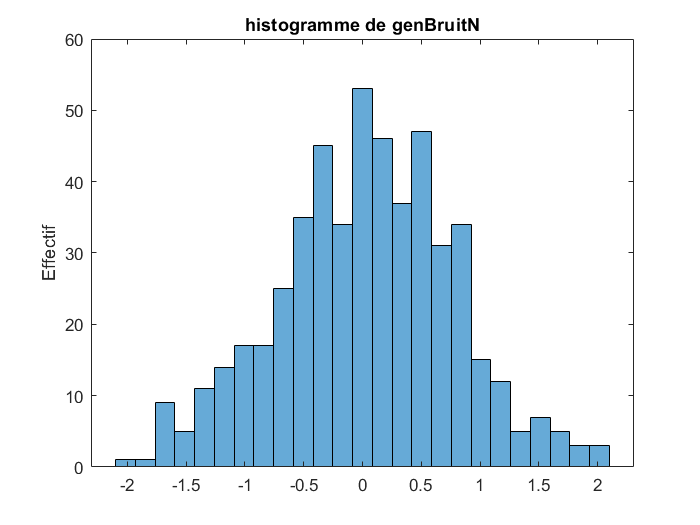

histogram(Bn, 25)
ylabel("Effectif")
title("histogramme de genBruitN")

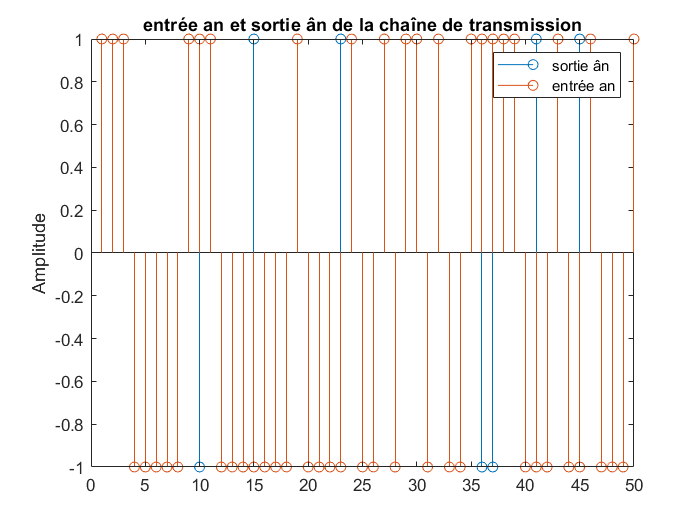

%histogram(Anf) %% inutile, on ne peut pas comparer

figure


stem(Anf)
ylabel("Amplitude")

hold on

stem(An)
title("entrée an et sortie ân de la chaîne de transmission")
legend("sortie ân", "entrée an")
xlim([0,50])

hold off

Taux d'erreur

NBerreur = sum(sign(abs(Anf-An)));
TauxErreur = NBerreur/N;


RSBNdB = 0:12;
RSBN = 10.^(RSBNdB*(1/10));

Var = 1./(2.*RSBN);

Txerreur = zeros(1,13);
Nberreur = zeros(1,13);
i = 1;

for s2 = Var
Bn2 = genBruitN(N, s2);
Rn2 = An + Bn2;
Anf2 = decodeBPSK(Rn2);
NBerreur = sum(sign(abs(Anf2-An)));
TauxErreur = NBerreur/N;
Txerreur(i)=TauxErreur;
Nberreur(i)=NBerreur;
i=1+i;
end

VectN =    -1.1348    0.0912   -1.4439    0.4733   -0.2726    1.1658    0.4195   -0.3684    0.4615    0.1856    0.3054   -0.7388    0.5375    1.4513   -0.5137    0.1540   -0.7178   -0.2060   -1.4499   -0.4245   -0.5725    0.1790   -0.9610   -0.0199    0.3372    1.7653    1.2682    0.5573    0.3195   -0.0965   -0.0982   -0.0877   -0.9823    1.4863   -0.7612   -0.7380    0.1148    0.2360   -0.2905    0.5616    0.3405   -0.5003    0.6121   -0.3404    0.9375   -0.0546   -0.2791   -0.5920    0.0319   -0.4455


VectAn =     -1     1    -1    -1    -1     1    -1    -1     1     1     1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1    -1     1     1    -1     1     1    -1     1    -1     1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =    -1.6857    0.4853   -0.3941    0.3615   -0.2879    0.6622   -0.8004   -1.0998    0.8596   -0.8531   -0.0611   -0.6461   -0.1886   -1.3527    0.2762    0.5688    1.0274   -1.1096   -0.6011    0.6511    1.3228   -0.6022   -0.5108   -0.4453    0.1297   -0.6454   -0.3108   -0.3938   -1.4947   -0.4191    0.9713    0.1833    0.3185   -1.1463   -0.0038   -0.7212   -0.3675   -1.0644   -1.2406    0.3324   -0.8427   -0.4194   -0.3688   -0.2823   -1.8208    0.3273    0.3852    0.8544    0.0739    1.1368


VectAn =     -1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1     1    -1     1    -1     1    -1    -1     1    -1    -1     1    -1    -1     1    -1     1    -1    -1     1     1     1    -1    -1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =     0.0003    0.7147    0.8942    0.4349   -0.1596   -0.6423    0.0454    0.1903   -0.0348   -0.0840   -0.2855   -0.6219   -0.5330    0.2263    0.9752   -0.4675   -0.1176    0.0439    0.6076   -0.8102    0.3243    0.1202    1.5552   -0.2275    1.4117    0.2941    0.0332   -0.6711   -0.7567   -0.9529    0.6541    0.7514   -1.1860    0.2257    0.4443   -0.7305   -0.5924   -1.0680   -0.0617   -0.4960    0.5583    0.1843   -0.4818   -0.5764   -0.1464    0.8680   -0.6710   -0.3518   -0.1528    0.2981


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1     1     1     1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1    -1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =     0.1440    0.0003   -0.1568    0.5406    0.1480    0.6633    0.2693   -0.4147    0.4933    0.2473   -0.6945   -0.3434   -0.1319    0.3586   -0.2531   -0.2516   -0.0925    0.5361    0.3750   -0.3928    0.2262    0.9656   -0.1018    0.2130    0.4217   -0.2040   -0.3115   -0.5456    0.4721   -0.0633   -0.0653   -0.4962    0.2988   -0.6731    1.0331    0.0053    0.1036    1.0773   -0.2082   -0.1897   -0.0920   -0.7364   -0.1770   -0.9963   -0.1125    0.1904   -0.4311   -1.1009    0.6530    0.2454


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =    -0.6304   -0.0519    0.5461   -0.2501    0.1026   -0.0268   -0.7273   -0.2844    0.1611    0.2759    0.1418   -0.0346   -0.5206    0.0983    0.3445    0.5639   -0.7068   -0.2168    0.4014   -0.2026    0.1450    0.1411   -0.3332   -0.6060    0.2080   -0.3349    0.1939   -0.5176   -0.3283    0.0279    0.8618   -0.2625   -0.3798    0.2952   -0.0942    0.0144    0.2662    0.3847   -0.5149    0.3597    0.2196    1.0605   -0.2824   -0.1730   -0.2966   -0.1770    1.0333   -0.0724   -0.1950   -0.2021


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1


VectN =    -0.1014    0.0471   -0.1288   -0.4344   -0.3664   -0.4269   -0.2755    0.5596    0.5936   -0.2825   -0.4522    0.1015   -0.1671    0.2690   -0.2514   -0.1908   -0.6809   -0.6386   -0.1610   -0.1650   -0.0850    0.6513    0.1564    0.4665    0.1415    0.4747   -0.2916   -0.3816   -0.3228   -0.4113    0.4398    0.5348   -0.2532    0.1409   -0.0016    0.5526    0.7476    0.2286   -0.3447    0.3848   -0.1293    0.2007    0.0260   -0.1064    0.1399   -0.7412   -0.4363    0.9791    0.4456   -0.1031


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =     0.0561    0.0974    0.1454   -0.2868    0.2346   -0.1918   -0.2297   -0.1142    0.1159    0.5287    0.0356   -0.5937    0.0684    0.5625   -0.1060   -0.3228   -0.1875    0.3756   -0.0999   -0.0100    0.5185   -0.0143   -0.3945   -0.1326   -0.3202   -0.1624    0.3635   -0.2146   -0.7226    0.1242   -0.3989    0.2656    0.1292   -0.0233   -0.5275    0.7173    0.0240   -0.0310    0.5095    0.0073   -0.3068    0.1003   -0.5184   -0.0073    0.0662   -0.1741    0.1094    0.8130    0.0076    0.7288


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =    -0.0361    0.1694    0.2340   -0.1365   -0.0581   -0.0620    0.1508   -0.0459   -0.5756   -0.6404    0.1837   -0.2784   -0.5522   -0.4641    0.0668   -0.0753    0.2594   -0.0152    0.0927   -0.6044   -0.1259    0.3685    0.7114   -0.1456    0.0503   -0.1066   -0.3035    0.3219    0.1213   -0.9751    0.0609   -0.5448    0.5507   -0.0937    0.0641   -0.0981    0.5221   -0.0107   -0.2717   -0.6163   -0.5715   -0.3633    0.1861    0.0279    0.7774    0.2796   -0.6225    0.3053    0.1520    0.2385


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =     0.3039   -0.2332    0.2270   -0.0620    0.3428    0.4628   -0.0962    0.6017   -0.6133    0.0432   -0.1556    0.0948   -0.4040   -0.3368   -0.0451   -0.0192   -0.5309    0.1092    0.0868    0.2476   -0.2676   -0.0307    0.1166   -0.0755    0.2897   -0.1152    0.0740   -0.0170   -0.1408   -0.5068    0.6091    0.4372    0.1887   -0.0292    0.0794   -0.0978   -0.5512    0.0786    0.5745   -0.1960    0.5214    0.4841    0.1261   -0.1953    0.2993    0.0478    0.5965    0.0433    0.1277    0.0777


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =     0.0520    0.2016   -0.2284   -0.1368   -0.4240    0.0169    0.0597   -0.1373   -0.1297    0.4193   -0.0133   -0.0416   -0.2613    0.2032    0.3303   -0.2989   -0.2094   -0.3722    0.3324    0.0001   -0.2555    0.3151   -0.0127    0.3812    0.1009    0.0374   -0.3636    0.1729    0.1347   -0.0887   -0.0372    0.0885   -0.0416    0.0289    0.2401    0.1297   -0.2354   -0.3049   -0.1383   -0.4615   -0.4761    0.2546   -0.3230   -0.3277   -0.3818    0.1705    0.2407   -0.1811    0.2744    0.2519


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =     0.1875    0.3213    0.0935    0.0499   -0.1200   -0.0220   -0.2444    0.3180   -0.2262    0.1441    0.1168    0.2409   -0.2215   -0.3482   -0.0549   -0.1736   -0.1245    0.1541    0.0847   -0.0868    0.0897    0.1133    0.3953    0.4678   -0.0815    0.1096   -0.1021    0.1430   -0.0530   -0.0757   -0.0171    0.0818   -0.1699   -0.5072   -0.3579    0.1218    0.0166   -0.0402   -0.4053    0.1331    0.0533    0.2370    0.0326    0.0362   -0.1982    0.1670   -0.2606   -0.0487   -0.2556   -0.0960


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =    -0.0114    0.0785   -0.0892   -0.0251    0.0619    0.0519   -0.0061   -0.1661   -0.0456    0.1088    0.1527   -0.0726   -0.2527   -0.0633    0.1702    0.1284   -0.5152   -0.0740    0.0170    0.0552   -0.0968   -0.1082    0.2131   -0.0571   -0.2150   -0.2042    0.0230    0.1570    0.0317   -0.0824    0.0888    0.2083    0.5271   -0.1669    0.3992   -0.0594   -0.1423    0.1448   -0.0434   -0.3236    0.2790    0.1371   -0.0440   -0.3835    0.2196    0.1674   -0.1010    0.0099   -0.2243    0.2814


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


VectN =    -0.1839   -0.1307   -0.1579   -0.1673   -0.1287    0.1950   -0.0324   -0.1704    0.0206   -0.2229    0.1578   -0.3678    0.1841    0.1346    0.2904   -0.3437   -0.1249    0.1755    0.1738    0.0098   -0.1399    0.1024   -0.3164    0.0821   -0.2288    0.1326   -0.0494    0.1891    0.0857    0.0441    0.1248    0.1043   -0.0066   -0.4105   -0.2803    0.0066    0.1818    0.0740    0.1732   -0.0184   -0.0645   -0.0694   -0.0384   -0.0194   -0.0285   -0.4893    0.0305    0.3280   -0.0064    0.1074


VectAn =      1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1     1     1     1    -1    -1    -1     1    -1    -1     1    -1    -1    -1     1


Txerreur

Txerreur =     0.0996    0.0703    0.0273    0.0156    0.0078    0.0059    0.0020         0         0         0         0         0         0


Nberreur

Nberreur =     51    36    14     8     4     3     1     0     0     0     0     0     0


Affichage Taux d'erreur en fonction de RSBNdB

Perreur = 0.5*erfc(sqrt(RSBN))

Perreur =     0.0786    0.0563    0.0375    0.0229    0.0125    0.0060    0.0024    0.0008    0.0002    0.0000    0.0000    0.0000    0.0000


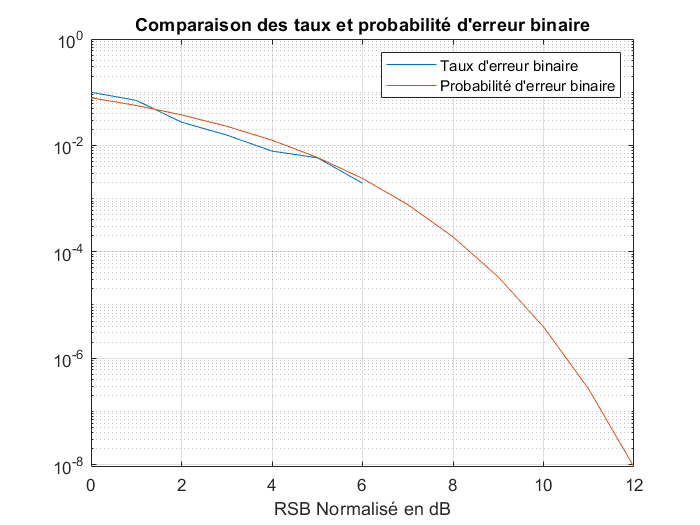



figure

semilogy(RSBNdB, Txerreur)
grid on
xlabel("RSB Normalisé en dB")
xlim([0,12])
hold on

semilogy(RSBNdB,Perreur )
legend("Taux d'erreur binaire", "Probabilité d'erreur binaire")
title("Comparaison des taux et probabilité d'erreur binaire")
hold off

Canal non idéal

N = 512

N = 512



An3=genBPSK(N)

An3 =     -1    -1    -1     1    -1    -1     1     1     1    -1     1    -1     1     1     1    -1     1    -1    -1    -1    -1     1    -1    -1     1    -1    -1     1     1    -1    -1    -1     1     1     1    -1     1    -1     1    -1     1     1     1     1    -1     1    -1    -1     1     1


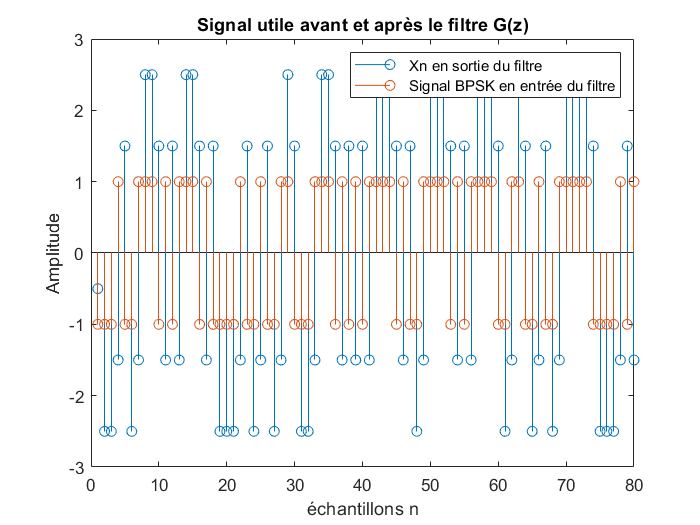

Xn = filter([0.5, 2], [1],An3);


stem(Xn)
xlabel("échantillons n")
xlim([0, 80])
ylim([-3,3])
ylabel("Amplitude")
title("Signal utile avant et après le filtre G(z)")

hold on

stem(An3)
legend("Xn en sortie du filtre", "Signal BPSK en entrée du filtre")

hold off

Taux d'erreur du canal non idéal

NBerreurBis = 0;
VectN = 1:N;

for n = VectN
    if sign(An3(n)) ~= sign(Xn(n))
        NBerreurBis = NBerreurBis +1;
    end
end

NBerreurBis = 1

NBerreurBis = 2

NBerreurBis = 3

NBerreurBis = 4

NBerreurBis = 5

NBerreurBis = 6

NBerreurBis = 7

NBerreurBis = 8

NBerreurBis = 9

NBerreurBis = 10

NBerreurBis = 11

NBerreurBis = 12

NBerreurBis = 13

NBerreurBis = 14

NBerreurBis = 15

NBerreurBis = 16

NBerreurBis = 17

NBerreurBis = 18

NBerreurBis = 19

NBerreurBis = 20

NBerreurBis = 21

NBerreurBis = 22

NBerreurBis = 23

NBerreurBis = 24

NBerreurBis = 25

NBerreurBis = 26

NBerreurBis = 27

NBerreurBis = 28

NBerreurBis = 29

NBerreurBis = 30

NBerreurBis = 31

NBerreurBis = 32

NBerreurBis = 33

NBerreurBis = 34

NBerreurBis = 35

NBerreurBis = 36

NBerreurBis = 37

NBerreurBis = 38

NBerreurBis = 39

NBerreurBis = 40

NBerreurBis = 41

NBerreurBis = 42

NBerreurBis = 43

NBerreurBis = 44

NBerreurBis = 45

NBerreurBis = 46

NBerreurBis = 47

NBerreurBis = 48

NBerreurBis = 49

NBerreurBis = 50

NBerreurBis = 51

NBerreurBis = 52

NBerreurBis = 53

NBerreurBis = 54

NBerreurBis = 55

NBerreurBis = 56

NBerreurBis = 57

NBerreurBis = 58

NBerreurBis = 59

NBerreurBis = 60

NBerreurBis = 61

NBerreurBis = 62

NBerreurBis = 63

NBerreurBis = 64

NBerreurBis = 65

NBerreurBis = 66

NBerreurBis = 67

NBerreurBis = 68

NBerreurBis = 69

NBerreurBis = 70

NBerreurBis = 71

NBerreurBis = 72

NBerreurBis = 73

NBerreurBis = 74

NBerreurBis = 75

NBerreurBis = 76

NBerreurBis = 77

NBerreurBis = 78

NBerreurBis = 79

NBerreurBis = 80

NBerreurBis = 81

NBerreurBis = 82

NBerreurBis = 83

NBerreurBis = 84

NBerreurBis = 85

NBerreurBis = 86

NBerreurBis = 87

NBerreurBis = 88

NBerreurBis = 89

NBerreurBis = 90

NBerreurBis = 91

NBerreurBis = 92

NBerreurBis = 93

NBerreurBis = 94

NBerreurBis = 95

NBerreurBis = 96

NBerreurBis = 97

NBerreurBis = 98

NBerreurBis = 99

NBerreurBis = 100

NBerreurBis = 101

NBerreurBis = 102

NBerreurBis = 103

NBerreurBis = 104

NBerreurBis = 105

NBerreurBis = 106

NBerreurBis = 107

NBerreurBis = 108

NBerreurBis = 109

NBerreurBis = 110

NBerreurBis = 111

NBerreurBis = 112

NBerreurBis = 113

NBerreurBis = 114

NBerreurBis = 115

NBerreurBis = 116

NBerreurBis = 117

NBerreurBis = 118

NBerreurBis = 119

NBerreurBis = 120

NBerreurBis = 121

NBerreurBis = 122

NBerreurBis = 123

NBerreurBis = 124

NBerreurBis = 125

NBerreurBis = 126

NBerreurBis = 127

NBerreurBis = 128

NBerreurBis = 129

NBerreurBis = 130

NBerreurBis = 131

NBerreurBis = 132

NBerreurBis = 133

NBerreurBis = 134

NBerreurBis = 135

NBerreurBis = 136

NBerreurBis = 137

NBerreurBis = 138

NBerreurBis = 139

NBerreurBis = 140

NBerreurBis = 141

NBerreurBis = 142

NBerreurBis = 143

NBerreurBis = 144

NBerreurBis = 145

NBerreurBis = 146

NBerreurBis = 147

NBerreurBis = 148

NBerreurBis = 149

NBerreurBis = 150

NBerreurBis = 151

NBerreurBis = 152

NBerreurBis = 153

NBerreurBis = 154

NBerreurBis = 155

NBerreurBis = 156

NBerreurBis = 157

NBerreurBis = 158

NBerreurBis = 159

NBerreurBis = 160

NBerreurBis = 161

NBerreurBis = 162

NBerreurBis = 163

NBerreurBis = 164

NBerreurBis = 165

NBerreurBis = 166

NBerreurBis = 167

NBerreurBis = 168

NBerreurBis = 169

NBerreurBis = 170

NBerreurBis = 171

NBerreurBis = 172

NBerreurBis = 173

NBerreurBis = 174

NBerreurBis = 175

NBerreurBis = 176

NBerreurBis = 177

NBerreurBis = 178

NBerreurBis = 179

NBerreurBis = 180

NBerreurBis = 181

NBerreurBis = 182

NBerreurBis = 183

NBerreurBis = 184

NBerreurBis = 185

NBerreurBis = 186

NBerreurBis = 187

NBerreurBis = 188

NBerreurBis = 189

NBerreurBis = 190

NBerreurBis = 191

NBerreurBis = 192

NBerreurBis = 193

NBerreurBis = 194

NBerreurBis = 195

NBerreurBis = 196

NBerreurBis = 197

NBerreurBis = 198

NBerreurBis = 199

NBerreurBis = 200

NBerreurBis = 201

NBerreurBis = 202

NBerreurBis = 203

NBerreurBis = 204

NBerreurBis = 205

NBerreurBis = 206

NBerreurBis = 207

NBerreurBis = 208

NBerreurBis = 209

NBerreurBis = 210

NBerreurBis = 211

NBerreurBis = 212

NBerreurBis = 213

NBerreurBis = 214

NBerreurBis = 215

NBerreurBis = 216

NBerreurBis = 217

NBerreurBis = 218

NBerreurBis = 219

NBerreurBis = 220

NBerreurBis = 221

NBerreurBis = 222

NBerreurBis = 223

NBerreurBis = 224

NBerreurBis = 225

NBerreurBis = 226

NBerreurBis = 227

NBerreurBis = 228

NBerreurBis = 229

NBerreurBis = 230

NBerreurBis = 231

NBerreurBis = 232

NBerreurBis = 233

NBerreurBis = 234

NBerreurBis = 235

NBerreurBis = 236

NBerreurBis = 237

NBerreurBis = 238

NBerreurBis = 239

NBerreurBis = 240

NBerreurBis = 241

NBerreurBis = 242


TauxErreurBis = NBerreurBis/N

TauxErreurBis = 0.4727